## 连续系统的离散化

《控制之美卷2》P11

clear all;
close all;
clc;

### 连续系统状态空间方程

% 构建系统矩阵A
A = [0 1 ; -2 -3];
% 构建输入矩阵B
B = [0 ; 1];
% 构建输出矩阵C
C = [1 0];
% 构建直接传递矩阵D
D = 0;

%% 定义离散化步长
Ts = 0.2;
% Ts= 0.5;

### 按照离散化公式计算 F G

% Y = expm(X) 计算 X 的矩阵指数
% 但是如果 X 包含一组完整的特征向量 V 和对应特征值 D，则 [V,D] = eig(X) 且
% expm(X) = V*diag(exp(diag(D)))/V
% 注意： expm 与 exp 两个函数并不相同
Fd = expm(A*Ts)

Fd =     0.8452    0.2387
   -0.4773    0.1292


Gd = inv(A) * (Fd - eye(size(A,1))) * B

Gd =     0.0774
    0.2387


### 手动定义离散化之后的系统

sys_manual_d = ss(Fd, Gd, C, D, Ts)

sys_manual_d =
 
  A = 
            x1       x2
   x1   0.8452   0.2387
   x2  -0.4773   0.1292
 
  B = 
            u1
   x1  0.07741
   x2   0.2387
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
采样时间: 0.5 seconds
离散时间状态空间模型。


### 由Matlab自动离散化的系统

sys_auto_d = c2d(ss(A,B,C,D),Ts)

sys_auto_d =
 
  A = 
            x1       x2
   x1   0.8452   0.2387
   x2  -0.4773   0.1292
 
  B = 
            u1
   x1  0.07741
   x2   0.2387
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
采样时间: 0.5 seconds
离散时间状态空间模型。


比较系统响应可以知道，手动推导的离散化系统是正确的

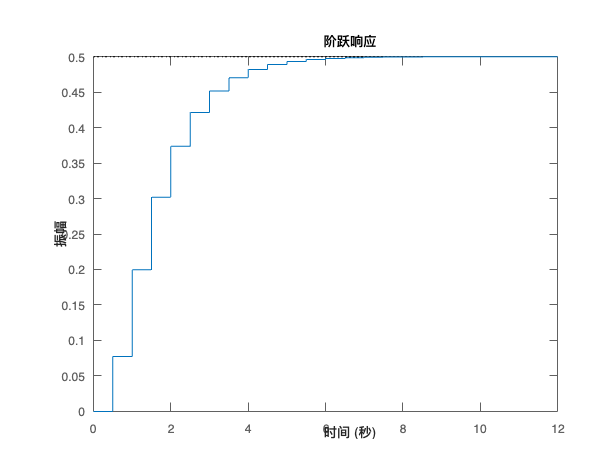

step(sys_auto_d)

step(sys_manual_d)

### 进一步地，深入探讨矩阵指数expm(A)

% 由特征值分解，计算矩阵指数
% 如果矩阵包含一组完整的特征向量 V 和对应特征值 D
[V,D] = eig(A*Ts)

V =     0.7071   -0.4472
   -0.7071    0.8944


D =    -0.5000         0
         0   -1.0000


Fd_manual = V * diag(exp(diag(D))) * inv(V)

Fd_manual =     0.8452    0.2387
   -0.4773    0.1292


Fd

Fd =     0.8452    0.2387
   -0.4773    0.1292


对比可知，由特征值分解得到的Fd_manual与系统自动计算得到的值相同。